
% Preparation
clear;
addpath(pathdef_local)

%% Script settings
LOG_FILE_BASE_NAME = 'DataLog_exp1_'; 
LOG_FILE_ENDING   = '.bin';     
INPUT_FOLDER = 'measurments/12_07_stiffness_axis2/';
ENCODER_OFFSET_LOAD_TXT = 'EncoderOffsetLoad.txt';
SAMPLE_FREQ = 500;

tSample = 1 / SAMPLE_FREQ; % Sample time


## Load and save data


expData = loadRobotData(tSample, INPUT_FOLDER, LOG_FILE_BASE_NAME, LOG_FILE_ENDING);

Nr. of data samples: 45194


save([INPUT_FOLDER, 'expData.mat'], '-struct', 'expData')


## Plot data

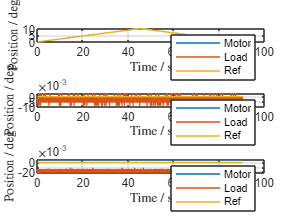

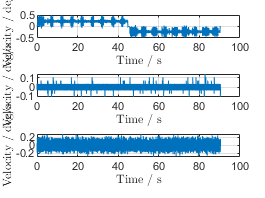

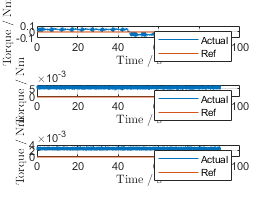

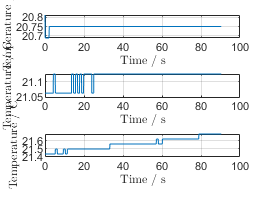


plotRobotData(expData);